# **SS - lab S4 - Zeic Beniamin**

#### Exercise 1

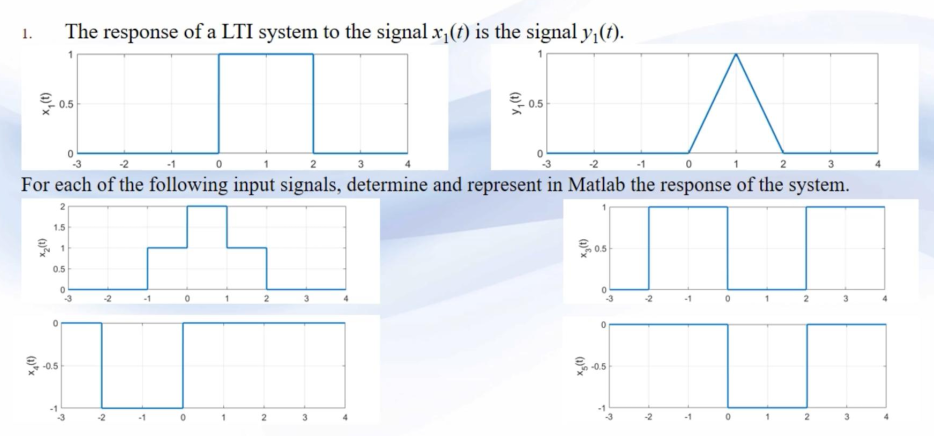

% Define the unit step function
u0 = @(x)(x>=0);

% Define a linear space
t = linspace(-3,4,200);

% Define the input and ouptut signals
in = @(x)(u0(x)-u0(x-2));
out = @(x)((u0(x)-u0(x-2)).*(1-abs(x-1)))

out = function_handle with value:
    @(x)((u0(x)-u0(x-2)).*(1-abs(x-1)))


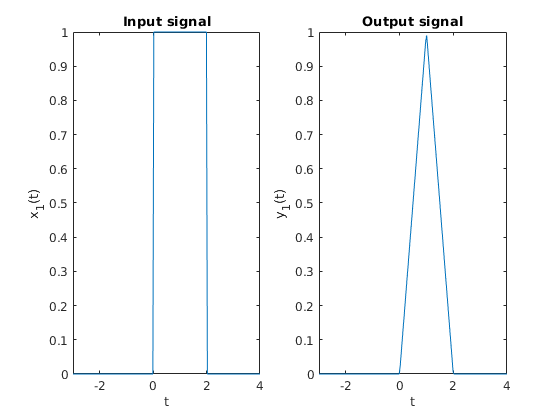


subplot(1,2,1);
plot(t, in(t));
title("Input signal");
xlabel('t')
ylabel('x_1(t)')
subplot(1,2,2);
plot(t, out(t));
title("Output signal");
xlabel('t')
ylabel('y_1(t)')

The signal x2(t), from the third graph is a composition of  several versions of the signal x1(t). Therefore, based on the fact that our system is an LTI system, we can decompose x2(t) and write it as a function of x1(t). The ouptut of the system will be the original output y1(t) on which we apply the same operations that we applied on x1(t) in order to convert it to x2(t)

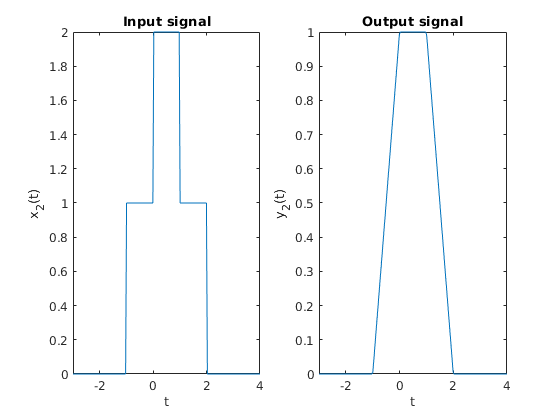

% Define x2(t) as a composition of two input signals
x2 = @(x)(in(t+1)+in(t));
% Define y2(t) as the same composition, but replace x1(t) with y1(t)
y2 = @(x)(out(t+1)+out(t));

subplot(1,2,1);
plot(t, x2(t));
title("Input signal");
xlabel('t')
ylabel('x_2(t)')
subplot(1,2,2);
plot(t, y2(t));
title("Output signal");
xlabel('t')
ylabel('y_2(t)')

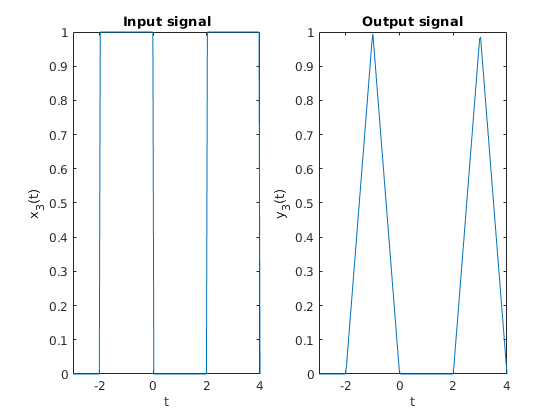

% Define x2(t) as a composition of two input signals
x3 = @(x)(in(t+2)+in(t-2));
% Define y2(t) as the same composition, but replace x1(t) with y1(t)
y3 = @(x)(out(t+2)+out(t-2));

subplot(1,2,1);
plot(t, x3(t));
title("Input signal");
xlabel('t')
ylabel('x_3(t)')
subplot(1,2,2);
plot(t, y3(t));
title("Output signal");
xlabel('t')
ylabel('y_3(t)')

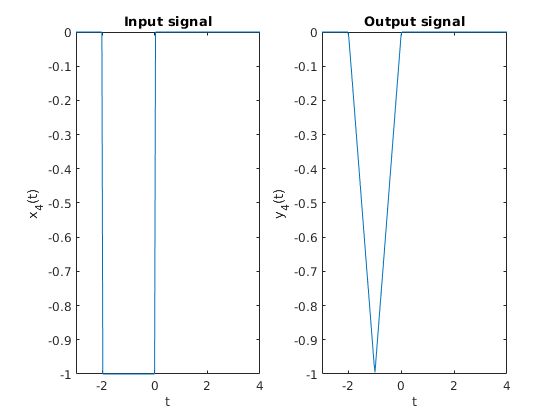

% Define x2(t) as a composition of two input signals
x4 = @(x)(-in(t+2));
% Define y2(t) as the same composition, but replace x1(t) with y1(t)
y4 = @(x)(-out(t+2));

subplot(1,2,1);
plot(t, x4(t));
title("Input signal");
xlabel('t')
ylabel('x_4(t)')
subplot(1,2,2);
plot(t, y4(t));
title("Output signal");
xlabel('t')
ylabel('y_4(t)')

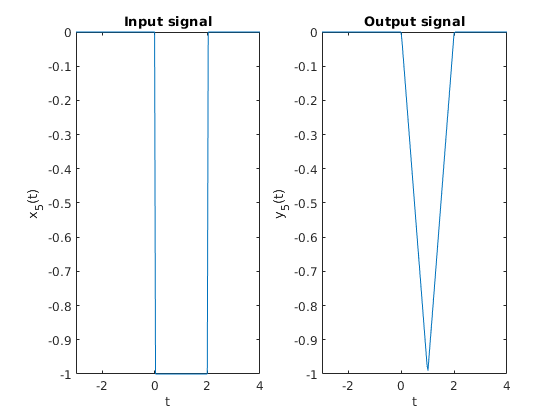

% Define x2(t) as a composition of two input signals
x5 = @(x)(-in(t));
% Define y2(t) as the same composition, but replace x1(t) with y1(t)
y5 = @(x)(-out(t));

subplot(1,2,1);
plot(t, x5(t));
title("Input signal");
xlabel('t')
ylabel('x_5(t)')
subplot(1,2,2);
plot(t, y5(t));
title("Output signal");
xlabel('t')
ylabel('y_5(t)')

#### Exercise 2

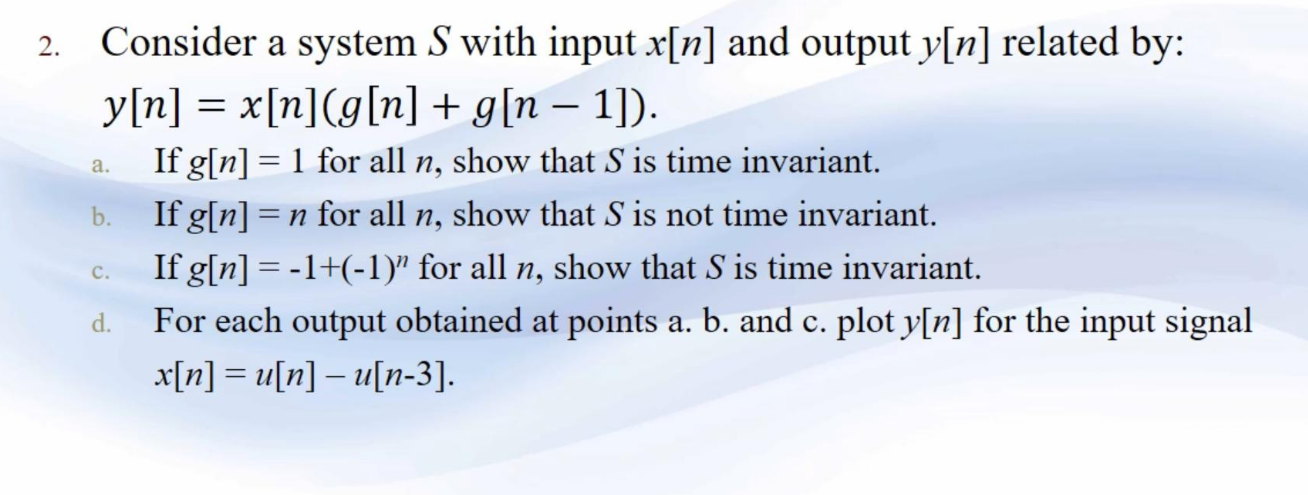

Points a, b, c are solved on paper and attached at the end of this pdf document.

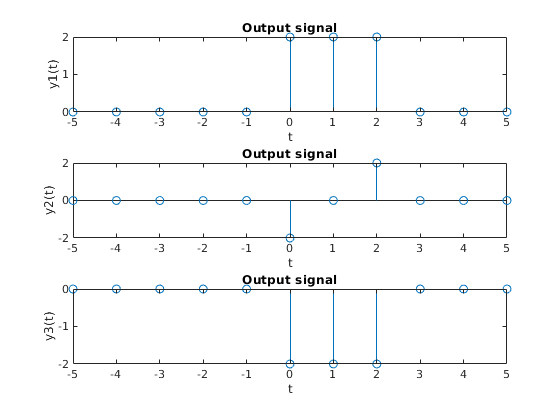

clear all;

% Define the unit step function
u0 = @(x)(x>=0);

% Define the input signal
in = @(n)(u0(n) - u0(n-3));

% Define the three system equations 
y1 = @(x) (2*in(x));
y2 = @(x) (2*(x-1).*in(x));
y3 = @(x) (-2*in(x));

% Plot the three graphs, each corresponding to a system
n = -5:5;

subplot(3,1,1);
stem(n, y1(n));
title("Output signal");
xlabel('t')
ylabel('y1(t)')

subplot(3,1,2);
stem(n, y2(n));
title("Output signal");
xlabel('t')
ylabel('y2(t)')

subplot(3,1,3);
stem(n, y3(n));
title("Output signal");
xlabel('t')
ylabel('y3(t)')

#### Exercise 3

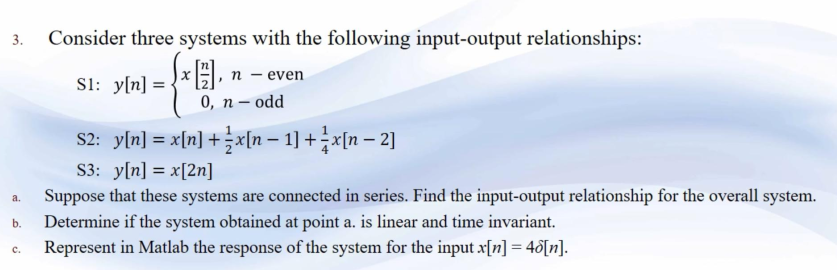

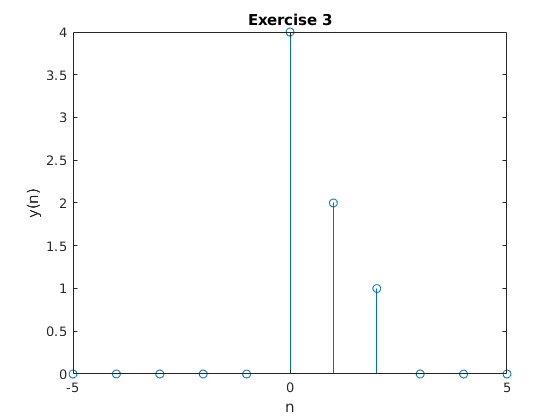

% Define the delta function
delta = @(x)(x==0);

in = @(x) (4*delta(x));
% Write the system equation
y = @(n)(in(n) + 1/2*in(n-1) + 1/4*in(n-2));

n = -5:5;
subplot(1,1,1);
stem(n, y(n));
title("Exercise 3");
xlabel('n')
ylabel('y(n)')